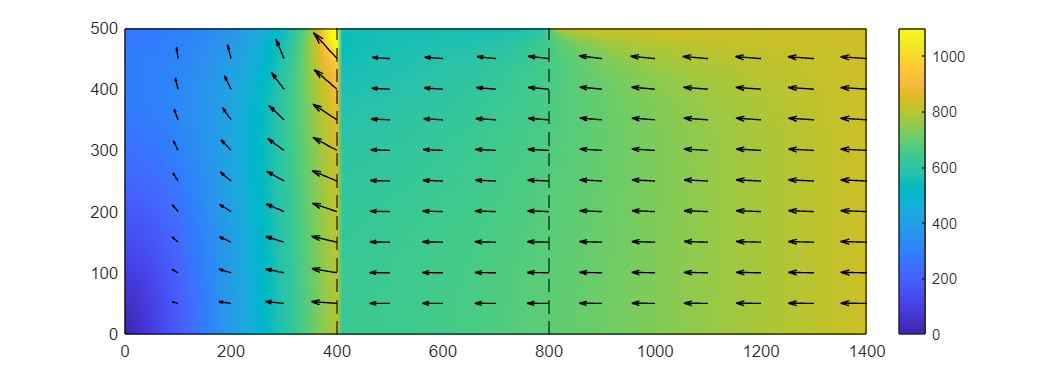

packing_ratio = 5;
thick_filament_half_spacing = (45/sqrt(3))*10^(-9);
thick_radius = 7*10^(-9);
thin_radius = 5*10^(-9);
L_thin = 1000e-9;
L_thick = 800e-9;
Contraction = 50;
R = 500*10^(-9);
L = L_thick + L_thin - Contraction*L_thick/100;
N = 50;
r_points = 101;
z_points = 141;

R_thick = thick_radius / thick_filament_half_spacing;
R_thin = thin_radius / thick_filament_half_spacing;
L1 = L - L_thin;
L2 = L_thick;
L1 = L1/L;
L2 = L2/L;

if packing_ratio == 2
    fully_dimensionless_lateral_permeabilities = [0.1864, 0.0362, 0.0938];
    fully_dimensionless_axial_permeabilities = [0.3729, 0.0728, 0.2038];
    beta = 0.6175;
elseif packing_ratio == 3
    fully_dimensionless_lateral_permeabilities = [0.1864, 0.0212, 0.0435];
    fully_dimensionless_axial_permeabilities = [0.3729, 0.0433, 0.1071];
    beta = 0.7127;
elseif packing_ratio == 5
    fully_dimensionless_lateral_permeabilities = [0.1864, 0.00618, 0.00737];
    fully_dimensionless_axial_permeabilities = [0.3729, 0.0247, 0.0759];
    beta = 0.7238;
end
porosities = [1 - 2*sqrt(3)*pi*(R_thick^2/12); 1 - 2*sqrt(3)*pi*(packing_ratio*R_thin^2/12 + R_thick^2/12); 1 - 2*sqrt(3)*pi*(packing_ratio*R_thin^2/12)];

k_perp_vector = (fully_dimensionless_lateral_permeabilities*thick_filament_half_spacing^2/R^2).';
k_parallel_vector = (fully_dimensionless_axial_permeabilities*thick_filament_half_spacing^2/L^2).';

lambda = bessel_zeros(1:N);
G = zeros(3, N);

for j = 1:3
    for n = 1:N
        G(j, n) = lambda(n)*sqrt(k_perp_vector(j)/k_parallel_vector(j));
    end
end
coefficients = zeros(6, N);

for n = 1:N
    M = zeros(6, 6);
    M(1, 1) = exp(-G(1, n)*L1);
    M(1, 2) = -1;
    
    M(2, 5) = 1;
    M(2, 6) = -exp(-G(3, n)*(1-L2));
    
    M(3, 1) = k_parallel_vector(1)*G(1, n);
    M(3, 2) = -k_parallel_vector(1)*G(1, n)*exp(-G(1, n)*L1);
    M(3, 3) = -k_parallel_vector(2)*G(2, n)*exp(-G(2, n)*(L2-L1));
    M(3, 4) = k_parallel_vector(2)*G(2, n);
    
    M(4, 3) = k_parallel_vector(2)*G(2, n);
    M(4, 4) = -k_parallel_vector(2)*G(2, n)*exp(-G(2, n)*(L2-L1));
    M(4, 5) = -k_parallel_vector(3)*G(3, n)*exp(-G(3, n)*(1-L2));
    M(4, 6) = k_parallel_vector(3)*G(3, n);
    
    M(5, 1) = 1;
    M(5, 2) = exp(-G(1, n)*L1);
    M(5, 3) = -exp(-G(2, n)*(L2-L1));
    M(5, 4) = -1;
    
    M(6, 3) = 1;
    M(6, 4) = exp(-G(2, n)*(L2-L1));
    M(6, 5) = -exp(-G(3, n)*(1-L2));
    M(6, 6) = -1;
    
    v = zeros(6, 1);
    I_n = 2 / (lambda(n)*besselj(1, lambda(n)));
    v(3) = beta*porosities(2) + (1 - porosities(3));
    v(4) = porosities(3) - beta*porosities(2);
    v = v*I_n;
    
    coefficients(:, n) = linsolve(M, v);
end

A = [coefficients(1,:); coefficients(3,:); coefficients(5,:)];
B = [coefficients(2,:); coefficients(4,:); coefficients(6,:)];

z_Darcy = linspace(0, 1, z_points);
r_Darcy = linspace(0, 1, r_points);

regions = zeros(length(z_Darcy), 1);
for k = 1:length(z_Darcy)
    if z_Darcy(k) <= L1
        regions(k) = 1;
    elseif z_Darcy(k) <= L2
        regions(k) = 2;
    else
        regions(k) = 3;
    end
end

gamma = [0; beta; 1];

p_Darcy = zeros(length(r_Darcy), length(z_Darcy));
u_r_Darcy = zeros(length(r_Darcy), length(z_Darcy));
w_Darcy = zeros(length(r_Darcy), length(z_Darcy));
u_r_Int = zeros(length(r_Darcy), length(z_Darcy));
w_Int = zeros(length(r_Darcy), length(z_Darcy));
for a = 1:length(r_Darcy)
    w_Darcy(a, :) = -gamma(regions).*porosities(regions);
end
L_vector = [0, L1, L2, 1];
for n = 1:N
    p_Darcy = p_Darcy + besselj(0, lambda(n)*r_Darcy.')*((A(regions, n).*exp(G(regions, n).*(z_Darcy.' - L_vector(regions+1).')) + B(regions, n).*exp(-G(regions, n).*(z_Darcy.' - L_vector(regions).'))).');
    u_r_Darcy = u_r_Darcy + besselj(1, lambda(n).*r_Darcy.')*(k_perp_vector(regions).*lambda(n).*(A(regions, n).*exp(G(regions, n).*(z_Darcy.' - L_vector(regions+1).')) + B(regions, n).*exp(-G(regions, n).*(z_Darcy.' - L_vector(regions).')))).';
    w_Darcy = w_Darcy - besselj(0, lambda(n).*r_Darcy.')*(k_parallel_vector(regions).*G(regions, n).*(A(regions, n).*exp(G(regions, n).*(z_Darcy.' - L_vector(regions+1).')) - B(regions, n).*exp(-G(regions, n).*(z_Darcy.' - L_vector(regions).')))).';
end
for a = 1:length(r_Darcy)
    for b = 1:length(z_Darcy)
        w_Int(a, b) = w_Darcy(a, b)/porosities(regions(b));
        u_r_Int(a, b) = u_r_Darcy(a, b)/porosities(regions(b));
    end
end

x = linspace(0, L, z_points);
y = linspace(0, R, r_points);
U = 1000*1e-9;
[X, Y] = meshgrid(x, y);

xlim([0, L*1e9])
ylim([0, R*1e9])
hold on
magnitude_Darcy = 1e9*sqrt((u_r_Darcy*(U*R/L)).^2 + (w_Darcy*U).^2);
im = imagesc(1e9*[x(1), x(end)], 1e9*[y(1), y(end)], magnitude_Darcy);
im.Interpolation = 'bilinear';
hold on
xline(1e9*L1*L, '--k', 'LineWidth', 1)
xline(1e9*L2*L, '--k', 'LineWidth', 1)
xlim([0, 1e9*L])
x0=10;
y0=10;
width=300*(L/R);
height=300;
set(gcf,'position',[x0,y0,width,height])
%clim([-1e-7*1e9, 1.1e-6*1e9])
xline(0, 'k')
xline(1400, 'k')
yline(0, 'k')
yline(500, 'k')
colorbar
clim([0, 1100])
temp1 = linspace(1, length(y), 11);
temp1 = floor(temp1(2:(end-1)));
temp2 = linspace(1, length(x), 15);
temp2 = floor(temp2(2:(end)));
quiver(1e9*X(temp1, temp2), 1e9*Y(temp1, temp2), 6*1e7*U*w_Darcy(temp1, temp2), 6*1e7*(U*R/L)*u_r_Darcy(temp1, temp2), 'off', 'k')
hold off